## **Plots of biofilm growth simulation**

% adding cross section to 3D scatter
global plot_range thickness i_cells;
data_set = "gaussian_adder_36h";
switch data_set
    case 'data_4'
        plot_range = [-100 100 -100 100 0 35];
        num_sim = 1;
        num_files = 118;
    case 'data_20'
        plot_range = [-50 50 -50 50 0 35];
        num_sim = 20;
        num_files = 58;
    case 'data_adder'
        plot_range = [-150 150 -150 150 0 50];
        num_sim = 1;
        num_files = 118;
    case 'data_adder_12_07_21'
        plot_range = [-120 120 -120 120 0 50];
        num_sim = 1;
        num_files = 118;
    case 'data_adder_12_07_21_2'
        plot_range = [-120 120 -120 120 0 50];
        num_sim = 1;
        num_files = 118;
    case 'data_adder_12_07_21_3'
        plot_range = [-120 120 -120 120 0 50];
        num_sim = 1;
        num_files = 118;
    case 'data_adder_13_07_21_1'
        plot_range = [-120 120 -120 120 0 50];
        num_sim = 1;
        num_files = 118;
    case 'data_adder_13_07_21_2'
        plot_range = [-100 100 -100 100 0 40];
        num_sim = 1;
        num_files = 118;
    case 'adder_length_1'
        plot_range = [-120 120 -120 120 0 50];
        num_sim = 1;
        num_files = 118;
    case 'gaussian_adder_21'
        plot_range = [-150 150 -150 150 0 80];
        num_sim = 1;
        num_files = 118;
    case 'gaussian_adder_22'
        plot_range = [-150 150 -150 150 0 80];
        num_sim = 1;
        num_files = 118;
    case 'gaussian_adder_36h'
        plot_range = [-150 150 -150 150 0 35];
        num_sim = 1;
        num_files = 118;
end
i_cells =149;
for n = 1:num_sim
    file_path = sprintf('outputs/%s/Cells%d/%d.txt',data_set,n,i_cells);
    if n == 1
        cells = importdata(file_path);
    else
        cells = cat(1,cells,importdata(file_path));
    end
end
x1 = cells(:,4);
x2 = cells(:,7);
y1 = cells(:,5);
y2 = cells(:,8);
z1 = cells(:,6);
z2 = cells(:,9);
growth_rate = cells(:,17);
len = sqrt((x1-x2).^2 + (y1-y2).^2 + (z1-z2).^2);
lengths = cells(:,10);
pole_age_p = cells(:,27); % p age
pole_age_q = cells(:,28); % q age
pole_age_older = max(pole_age_p, pole_age_q);

avg_pole_age = (pole_age_p+pole_age_q)/2; % average pole age for cells
% average co-ordinates
x = (x1 + x2)/2;
y = (y1 + y2)/2;
z = (z1 + z2)/2;

%radial distance of cell
%Using the "." will effectively perform element-by-element mathematical operations
r = sqrt(x.^2 + y.^2);

**Set the size of the dots used in all subsequent scatter plots, and the thickness of all planar cross sections**

global thickness dot_size;
dot_size =4;
thickness =10;

%plt.color_scatter(x,y,z,dot_size,growth_rate, "growth rate");

## Cell Age

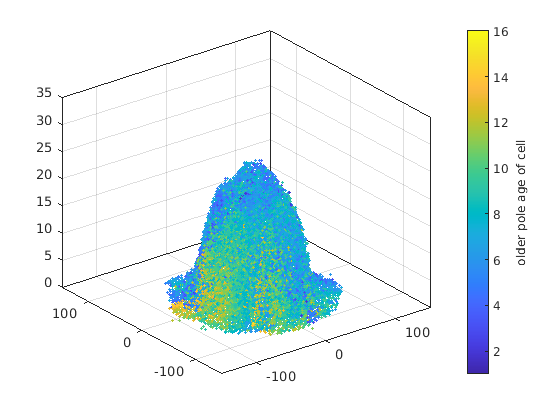

plt.color_scatter(x,y,z,dot_size,pole_age_older, "older pole age of cell")

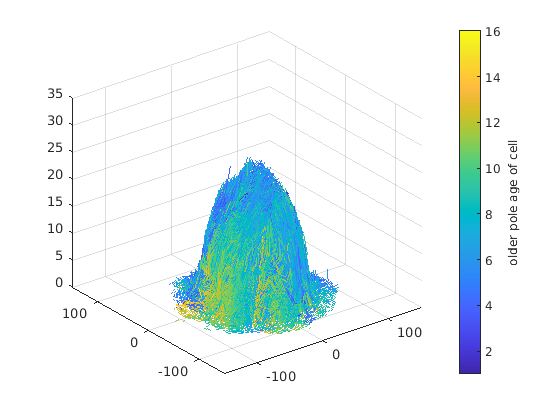

plt.color_quiver(x1,y1,z1,x2,y2,z2,pole_age_older,"older pole age of cell")

cross sections of the above plot in all 3 principle directions

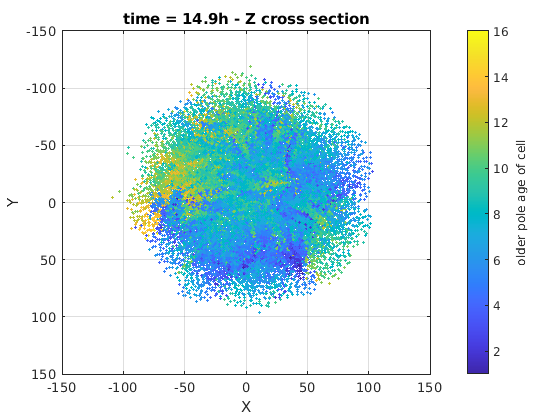

z_cut =0;
plt.color_scatter(x,y,z,dot_size,pole_age_older, "older pole age of cell", 'Z',z_cut)

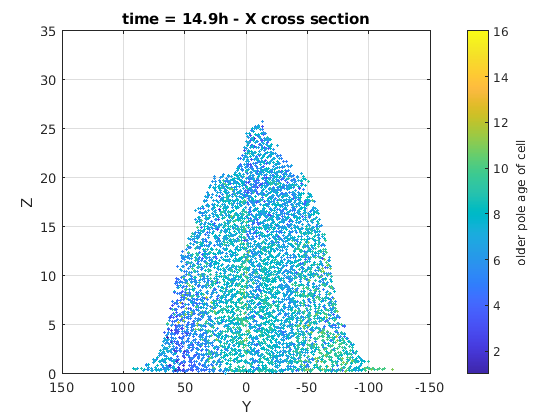

x_cut =-3;
plt.color_scatter(x,y,z,dot_size,pole_age_older, "older pole age of cell", 'X',x_cut)

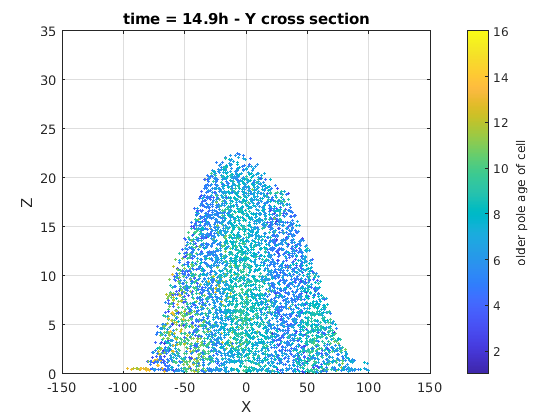

y_cut =2;
plt.color_scatter(x,y,z,dot_size,pole_age_older, "older pole age of cell", 'Y',y_cut)

### age plot trimmed to a radius

r_cut_age =8;
tube_thickness_age = 1;
i = find(r>r_cut_age & r<(r_cut_age+tube_thickness_age));

%plt.color_scatter(x(i),y(i),z(i),dot_size,pole_age_older(i), "older pole age of cell")

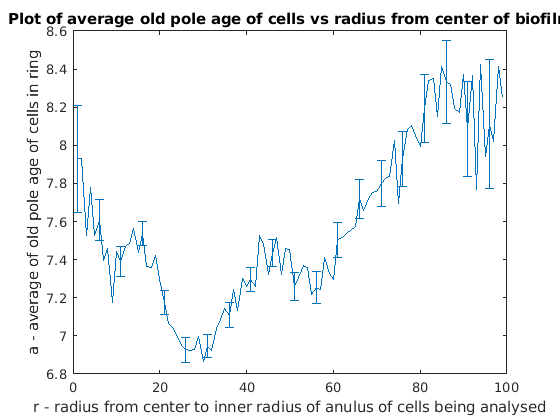

res = 1; %thickness of tubes being analysed
max_r = 100;
r_range = 1:res:(max_r-res); %https://uk.mathworks.com/help/matlab/ref/colon.html
avg_age = r_range;
SEM = r_range;

num_cells_in_ring = r_range;
cell_density_in_ring = r_range;
for i = 1:length(r_range)
    ring_indeces = find(r>r_range(i) & r<(r_range(i)+res));
    pole_ages_of_cells_in_ring = pole_age_older(ring_indeces);
    avg_age(i) = mean(pole_ages_of_cells_in_ring, 'all');
    SEM(i) = std(pole_ages_of_cells_in_ring)/sqrt(length(pole_ages_of_cells_in_ring));
    
    num_cells_in_ring(i) = length(ring_indeces);
    cell_density_in_ring(i) = num_cells_in_ring(i)/(2*pi*r_range(i));
end
used_SEM = NaN(length(SEM),1);
error_bar_res = 5;
for i = 1:error_bar_res:length(used_SEM)
    used_SEM(i) = SEM(i);
end
errorbar(r_range,avg_age,used_SEM,'vertical')
title('Plot of average old pole age of cells vs radius from center of biofilm')
xlabel('r - radius from center to inner radius of anulus of cells being analysed')
ylabel('a - average of old pole age of cells in ring')

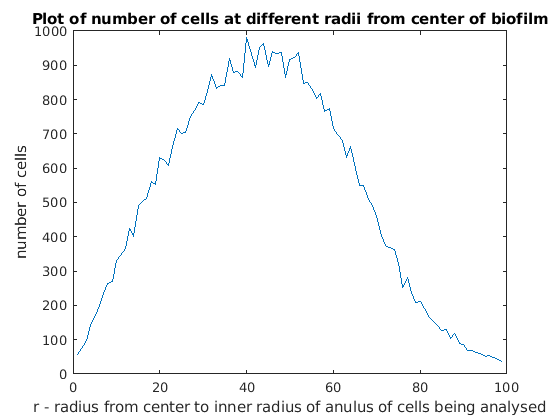

plot(r_range,num_cells_in_ring)

title('Plot of number of cells at different radii from center of biofilm')
xlabel('r - radius from center to inner radius of anulus of cells being analysed')
ylabel('number of cells')

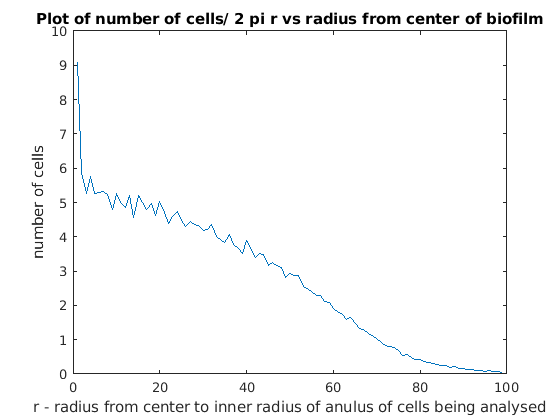


plot(r_range,cell_density_in_ring)

title('Plot of number of cells/ 2 pi r vs radius from center of biofilm')
xlabel('r - radius from center to inner radius of anulus of cells being analysed')
ylabel('number of cells')

## Cell Length - scatter

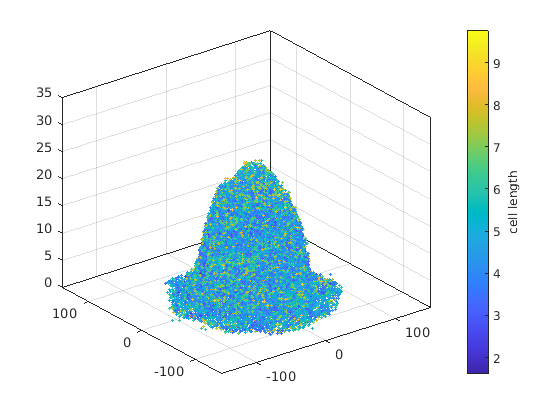

plt.color_scatter(x,y,z,dot_size,lengths, "cell length")

cross sections of the above plot in all 3 principle directions

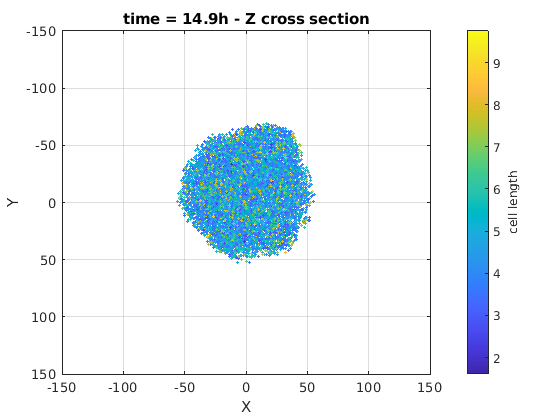

z_cut =12;
plt.color_scatter(x,y,z,dot_size,lengths, "cell length",'Z',z_cut)

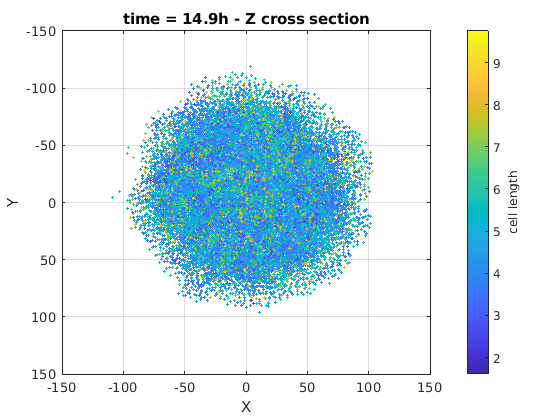

z_cut =0;
plt.color_scatter(x,y,z,dot_size,lengths, "cell length",'Z',z_cut)

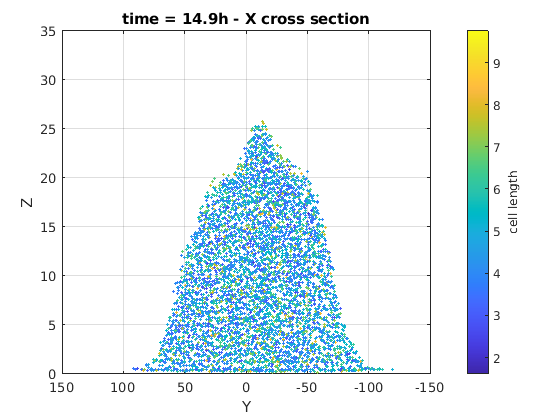

x_cut =0;
plt.color_scatter(x,y,z,dot_size,lengths, "cell length",'X',x_cut)

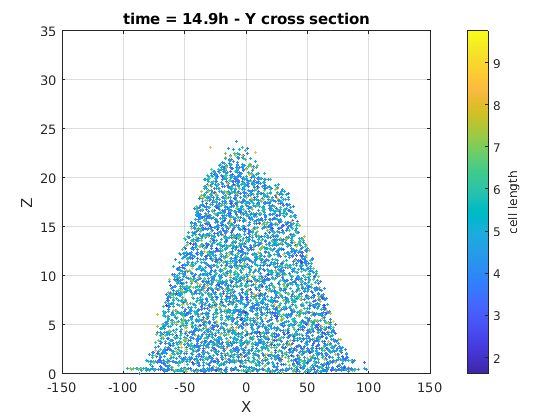

y_cut =0;
plt.color_scatter(x,y,z,dot_size,lengths, "cell length",'Y',y_cut)

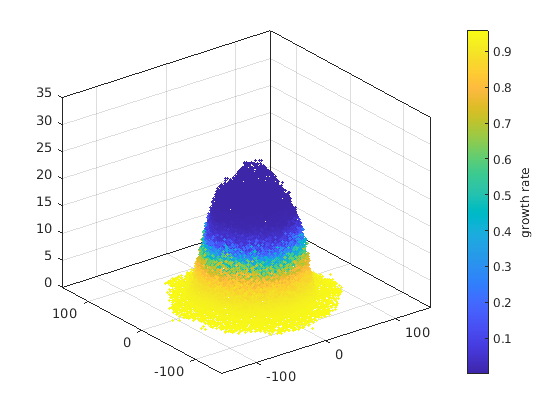

plt.color_scatter(x,y,z,dot_size,growth_rate, "growth rate");

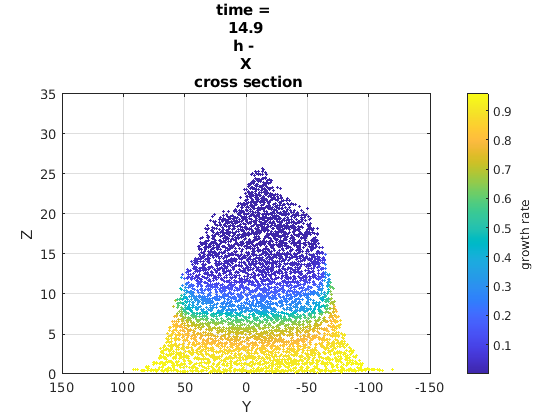

cut_axis = "X";
cut_value =0;
plt.color_scatter(x,y,z,dot_size,growth_rate, "growth rate",cut_axis,cut_value);

length plot trimmed to a radius

r_cut_length =11;
tube_thickness_length = 1;
i = find(r>r_cut_length & r<(r_cut_length+tube_thickness_length));

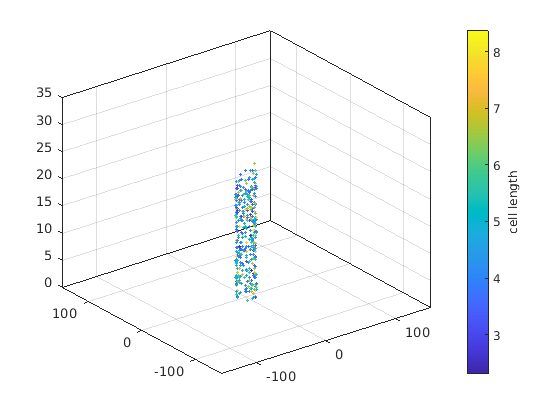

plt.color_scatter(x(i),y(i),z(i),dot_size,lengths(i), "cell length")

graphing average cell length for a certain radius as a 2d plot

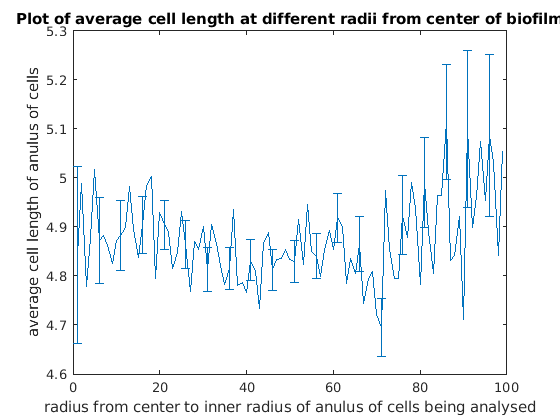

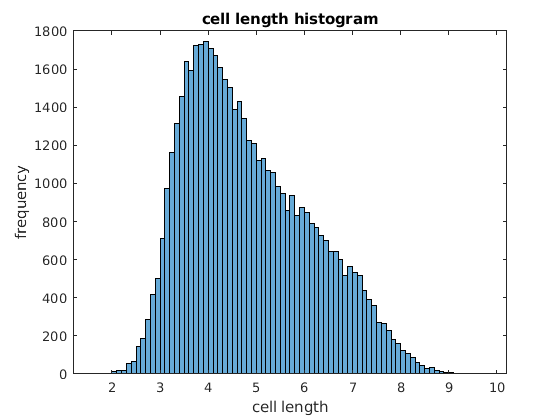

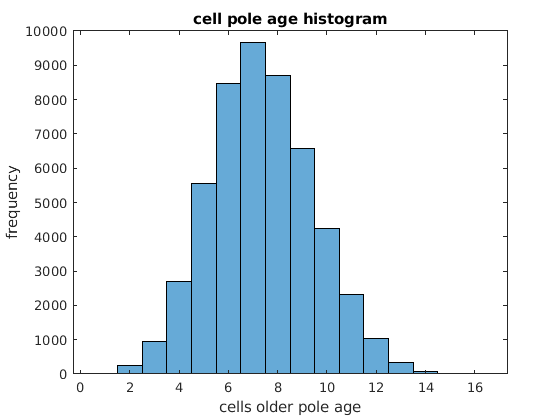

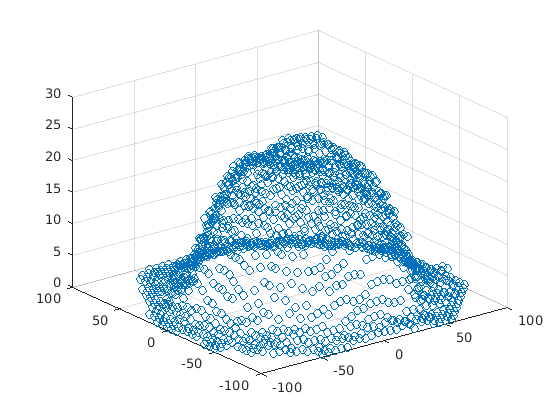

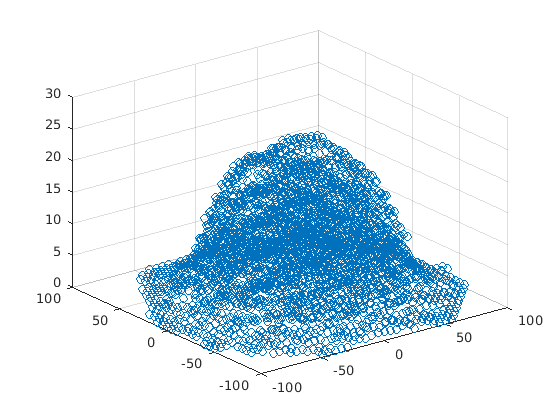

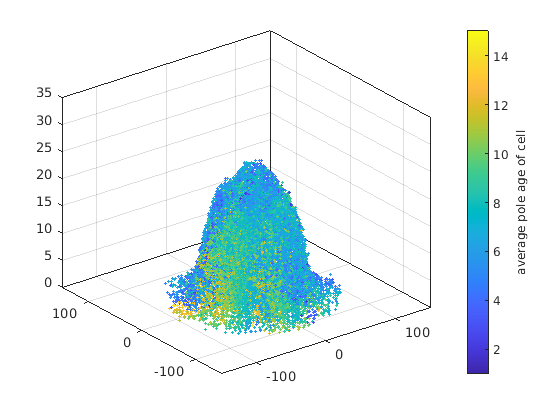

res = 1; %thickness of tubes being analysed
max_r = 100;
r_range = 1:res:(max_r-res); %https://uk.mathworks.com/help/matlab/ref/colon.html
avg_length = r_range;
for i = 1:length(r_range)
    ring_indeces = find(r>r_range(i) & r<(r_range(i)+res));
    lengths_of_cells_in_ring = lengths(ring_indeces);
    avg_length(i) = mean(lengths_of_cells_in_ring, 'all');
    SEM(i) = std(lengths_of_cells_in_ring)/sqrt(length(lengths_of_cells_in_ring));
end

used_SEM = NaN(length(SEM),1);
error_bar_res = 5;
for i = 1:error_bar_res:length(used_SEM)
    used_SEM(i) = SEM(i);
end
errorbar(r_range,avg_length,used_SEM,'vertical')
title('Plot of average cell length at different radii from center of biofilm')
xlabel('radius from center to inner radius of anulus of cells being analysed')
ylabel('average cell length of anulus of cells')